clear
clc
close all
tic

# Example of Bayesian Inference on 2 normal distributions

x = linspace(0,10,1000);
figure; 
hold on; 
axis([0 10 0 1]);

# Prior distribution

pm = 2; % Prior mean
ps2 = 100/12; % Prior variance
a=0;
b=10;
prior = 1/(b-a)*ones(1,1000);
plotPrior = plot(x,prior,'k',"LineWidth",3); % Plot 1: prior distribution
leg = legend('prior');

# Number of recursive iterations

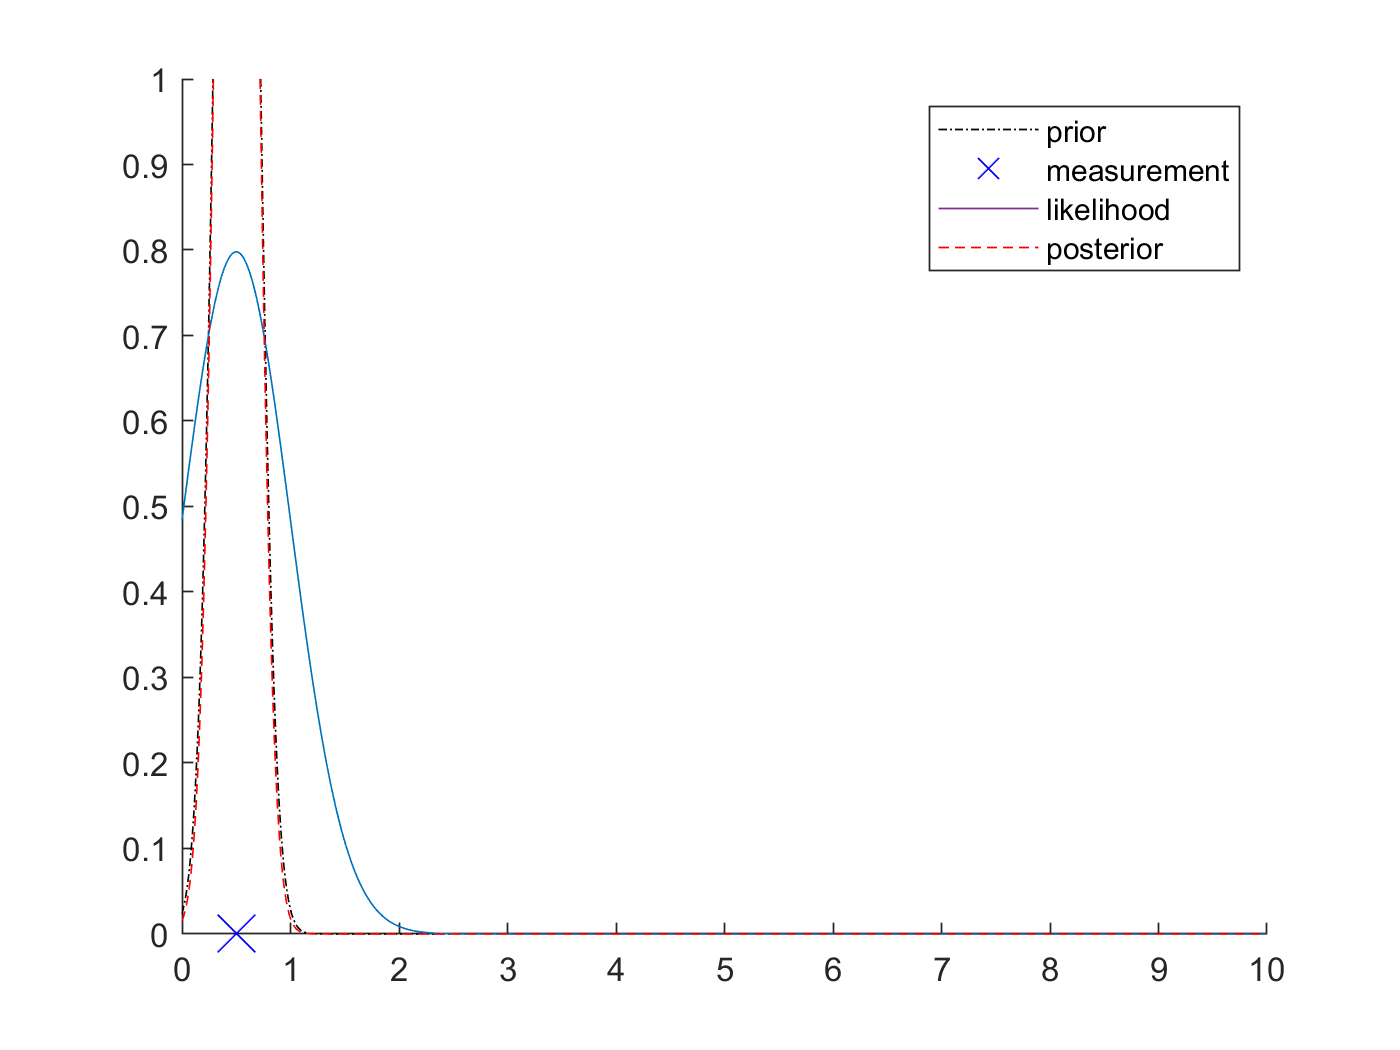

for i = 1:100
    % Likelihood function
    lm =0.5; % sample mean
    ls2 = 0.25; % sample variance
    Q=0.5;
    P=0.5;
    plotSample = plot(P, 0, 'bx', 'MarkerSize', 16); % Plot 2: sample mean
    leg = legend('prior', 'measurement');%#ok
    
    like = (2*pi*ls2)^(-0.5)*exp(-0.5*(x-lm).^2/ls2);
    plotLike = plot(x,like); % Plot 3: sample distribution
    leg = legend('prior', 'measurement', 'likelihood'); %#ok
    
    Ps2 = (1/ps2 + 1/ls2)^(-1);
    Pm = Ps2*(pm/ps2 + lm/ls2);
    posterior = (2*pi*Ps2)^(-0.5)*exp(-0.5*(x-Pm).^2/Ps2);
    plotPost = plot(x, posterior, 'r--'); % Plot 3: product distribution
    leg = legend('prior', 'measurement', 'likelihood', 'posterior');
    
    if(i < 10)
        
        pause(1);
        
        delete(get(leg, 'Children'));
        
        delete(plotPrior);
        delete(plotLike);
        delete(plotPost);
        delete(plotSample);
        
        prior = posterior; % Plot 3: product distribution
        pm = Pm;
        ps2 = Ps2;
        
        plotPrior = plot(x,prior,'k-.'); % Plot 1: prior distribution
        leg = legend('prior');
    end
end

toc

Elapsed time is 59.461023 seconds.
